# **Implementation of IEEE 802.11a WLAN Physical Layer (OFDM)**  

## **IEEE 802.11a:**

- **Introduction**

- **Transmitter Implementation**

- **Receiver Implementation**

- **Testing**

## Transimitter:

## Receiver:

## Testing:

- **Verification that the text files are received correctly for all supported rates**

- **Comparison between BER of the ZF and Weiner equalizer for 64QAM modulation, and 3/4 code rate (floating-point)**

- **Constellation of received symbols after ZF equalization, and Weiner equalizer for 64QAM modulation, and 3/4 code rate (floating-point)**

- **Comparison between BER of the floating-point and fixed-point implementations for 16QAM modulation, and 3/4 code rate**

- **Comparison between BER performance of all supported rates using the floating-point implementation  **

- **Comparison between BER performance of all supported rates using the Fixed-point implementation  **

## Introduction:

- **In this project, IEEE 802.11a WLAN Physical Layer (OFDM) is implmented. In OFDM, multiple closely spaced orthogonal subcarrier signals with overlapping spectra are transmitted to carry data in parallel. The number of subcarriers is 64, where only 48 subcarriers are used for the sake of data transmission and the rest of the 64 are zeroed to reduce adjacent channel interference. Convolutional encoding with rates 1/2, 2/3, and 3/4 are used for forward error correction. On the other hand, Veterbi decoder is used at the receiver to correct possible errors accumulated through noise. For channel estimation and equalization, both Zero Forcing (ZF), and Weiner Filter are used. Additionally, the modulation schemes that our implemented system supports are “BPSK”, “QPSK”, “16QAM” and “64QAM” with different rates up to 54 Mbps. The following diagram shows the main stages of our implmentation.**

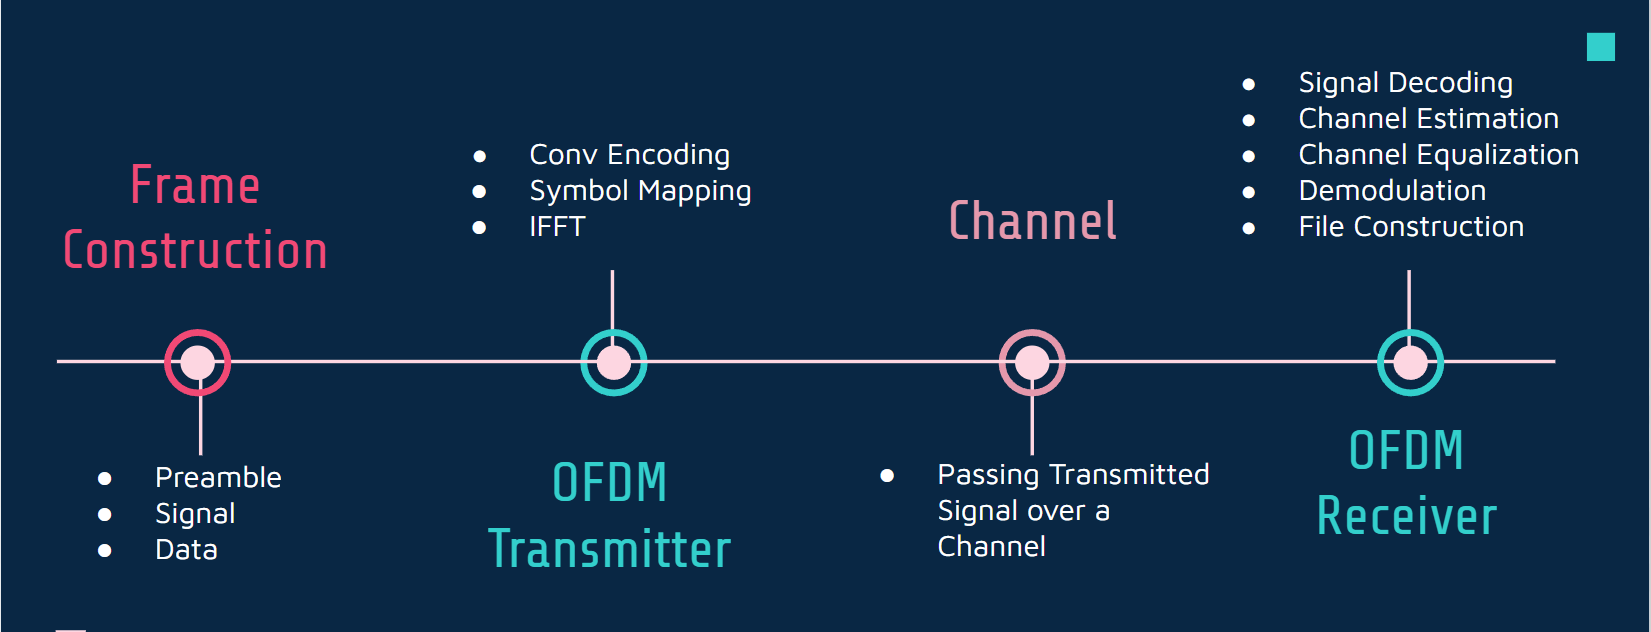

## Transmitter Implmentation:

**Data is one of the most important parts in the frame. firstly, we tried to read the file correctly to transmite it by following the below steps:**

- **FEC Coder: we use convolutional encoding for forward error correction with the following generator polynomials, g0 = 1011011, g1 = 1111001.**

- **Padding: to ensure that the whole data within the OFDM symbol will be mapped correctly with different types of Modulation.**

- **Symbol mapping: maps the bits to complex symbols according to each modulation type.**

- **The stream of complex numbers is divided into groups of 48 symbols and adding the pilots and the NULLs to pass it through IFFT with size 64.**

- **Adding cyclic prefix.**

- **Then sending the data across the channel.**

## Receiver Implmentation:

**Mainly, the reciver mission is to reverse each step happend at the transmiter (Coding, mapping,etc...) to receiver the data correctly.**

- **Removing cyclic prefix.**

- **passing the data through FFT block.**

- **Frequency equalization. **

- **Symbol demapping. **

- **FEC decoder.**

## Testing:

### **A) Verification that the text files are received correctly for all supported rates**

### **- test_file_1.txt**

- **6 Mbps, BPSK, 1/2**

clc
clear all
close all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 6; codeRate = 1/2; modulation_type = 'BPSK'; rep_type = 'Float'; equalization_method = 'WE';
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
%transmitted_frames = filter(h,1,transmitted_frames); 
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
%Receiver
[decoded_data, rec_frames, eq_rec_fremaes ] = Receiver(transmitted_frames, equalization_method, rep_type, 0);
output_fileID = fopen('output_test1_BPSK_6.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');


Received Text File

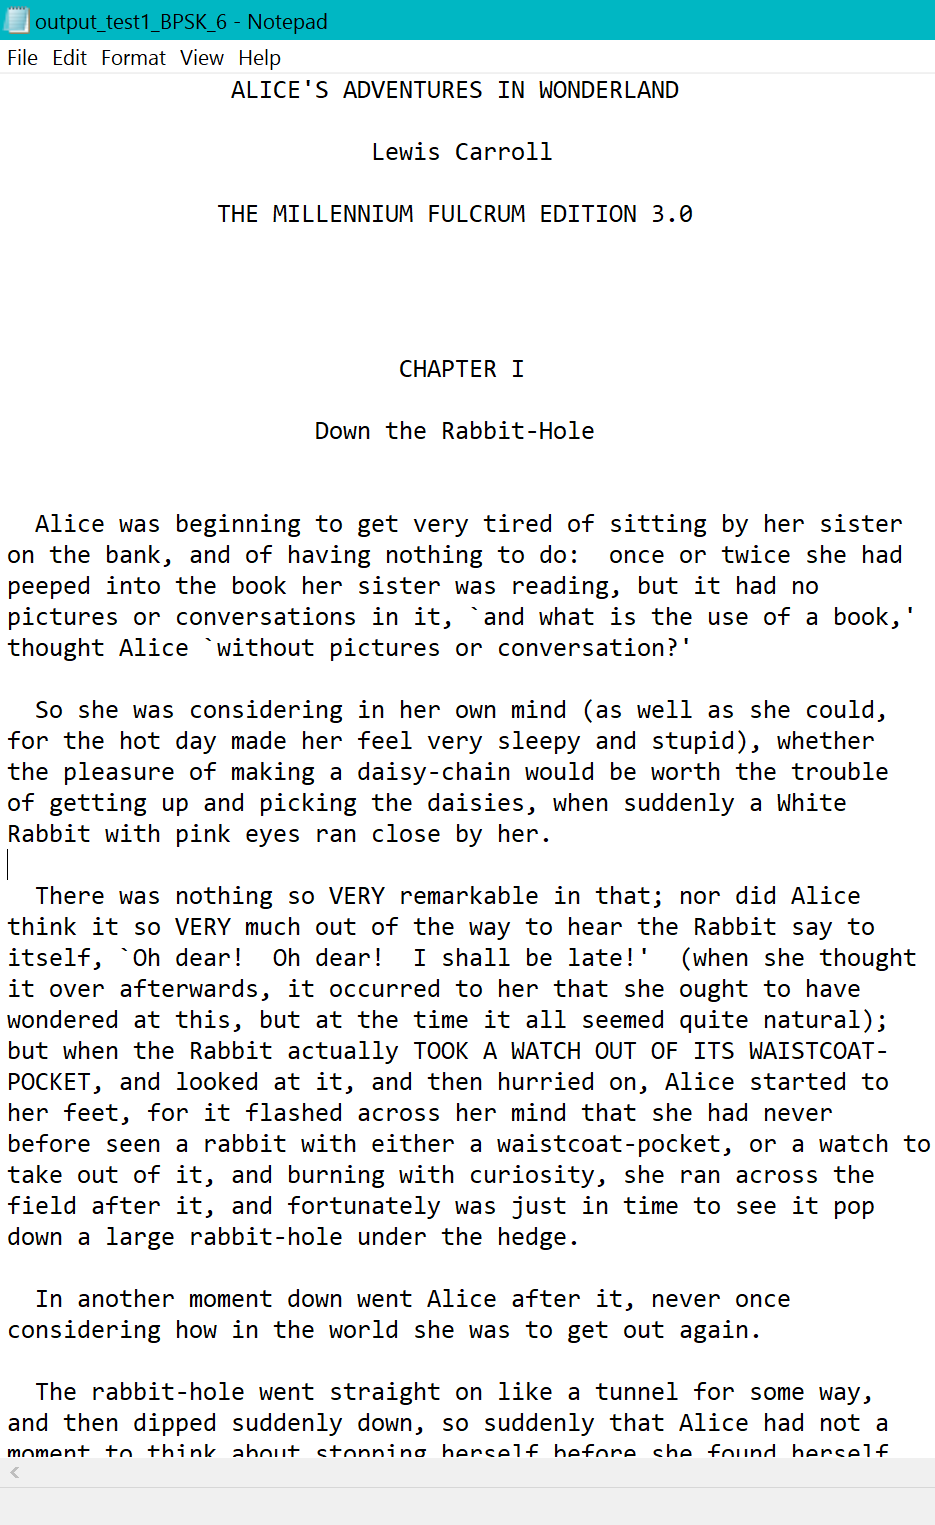

- **9 Mbps, BPSK, 3/4**

clc
clear all
close all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 9; codeRate = 3/4; modulation_type = 'BPSK'; rep_type = 'Float'; equalization_method = 'WE';
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
%transmitted_frames = filter(h,1,transmitted_frames); 
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
%Receiver
[decoded_data, rec_frames, eq_rec_fremaes ] = Receiver(transmitted_frames, equalization_method, rep_type);
output_fileID = fopen('output_test1_BPSK_9.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');


Received Text File

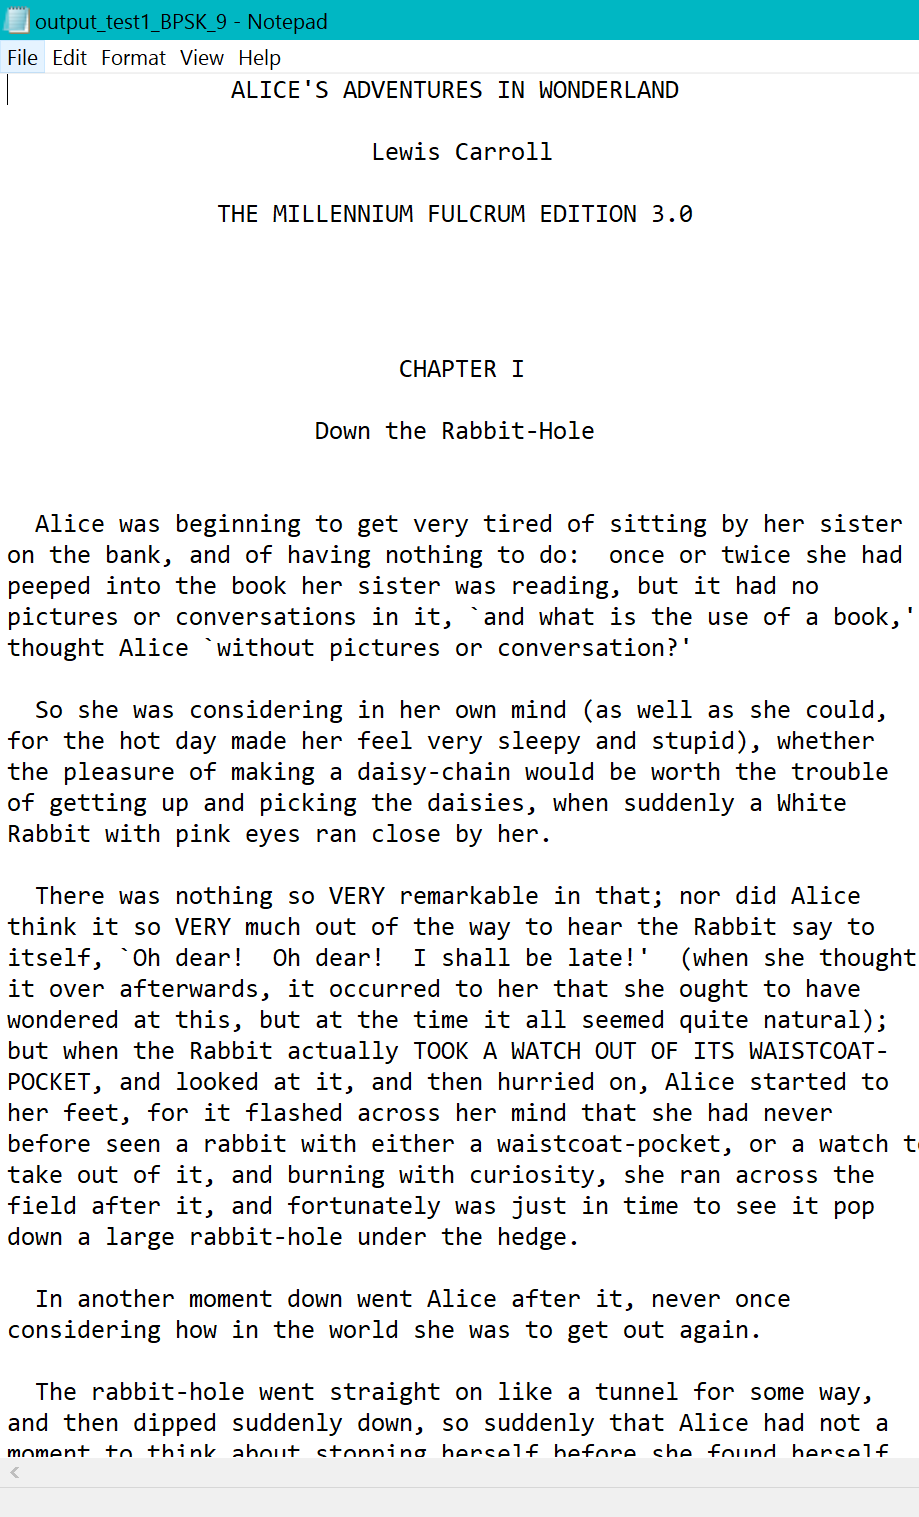

- **12 Mbps, QPSK, 1/2**

clc
clear all
close all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 12; codeRate = 1/2; modulation_type = 'QPSK'; rep_type = 'Float'; equalization_method = 'WE';
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
%transmitted_frames = filter(h,1,transmitted_frames); 
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
%Receiver
[decoded_data, rec_frames, eq_rec_fremaes ] = Receiver(transmitted_frames, equalization_method, rep_type);
output_fileID = fopen('output_test1_QPSK_12.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');


Received Text File

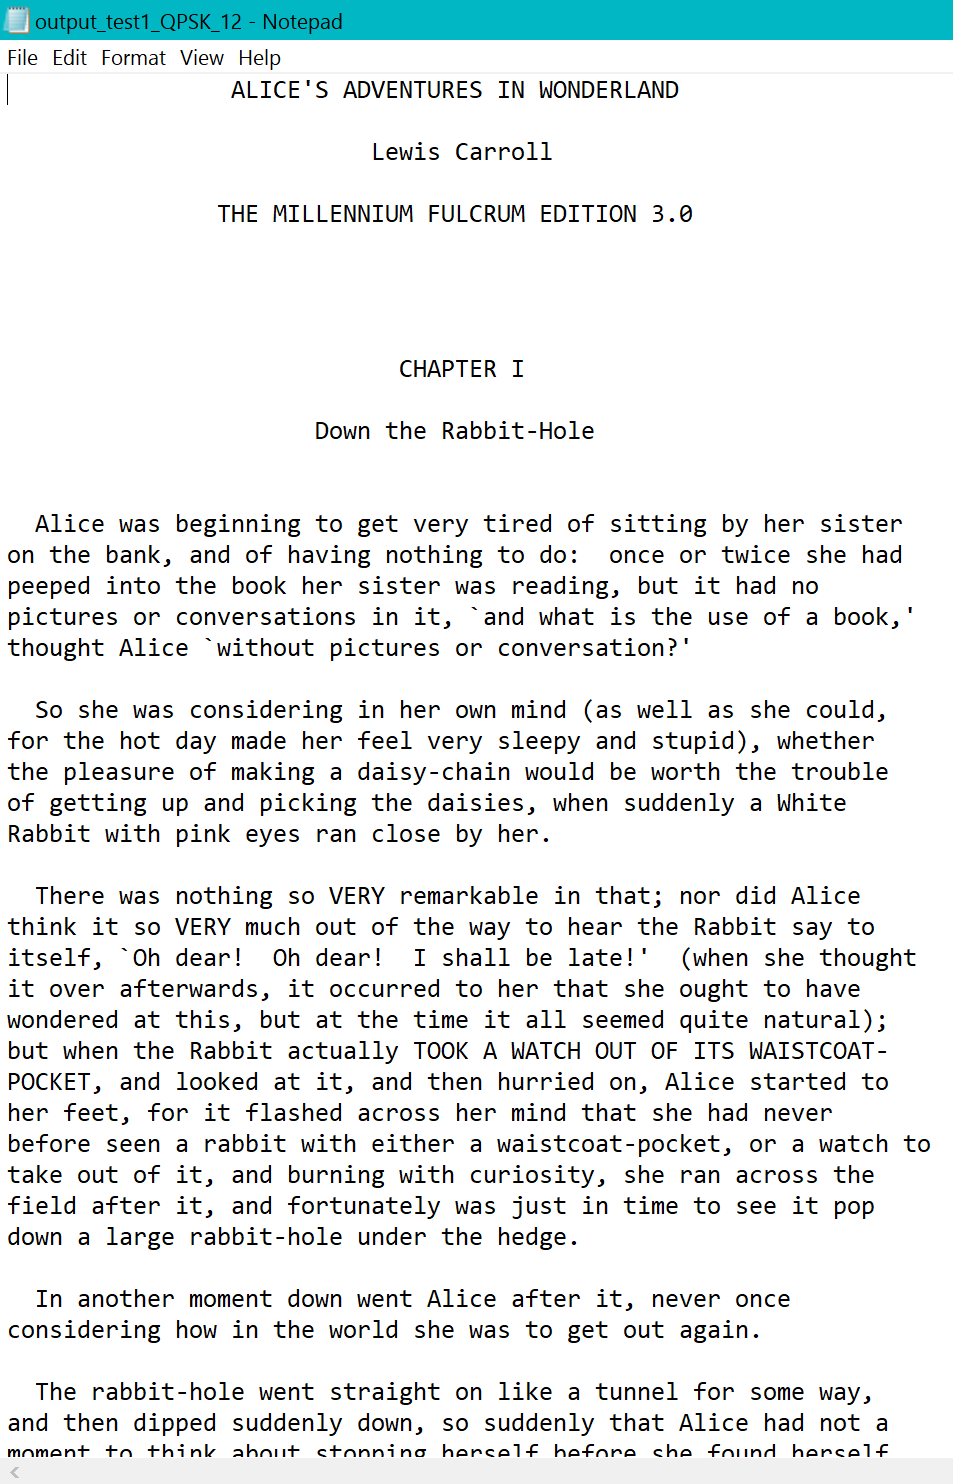

- **18 Mbps, QPSK, 3/4**

clc
clear all
close all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 18; codeRate = 3/4; modulation_type = 'QPSK'; rep_type = 'Float'; equalization_method = 'WE';
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
%transmitted_frames = filter(h,1,transmitted_frames); 
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
%Receiver
[decoded_data, rec_frames, eq_rec_fremaes ] = Receiver(transmitted_frames, equalization_method, rep_type);
output_fileID = fopen('output_test1_QPSK_18.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');


Received Text File

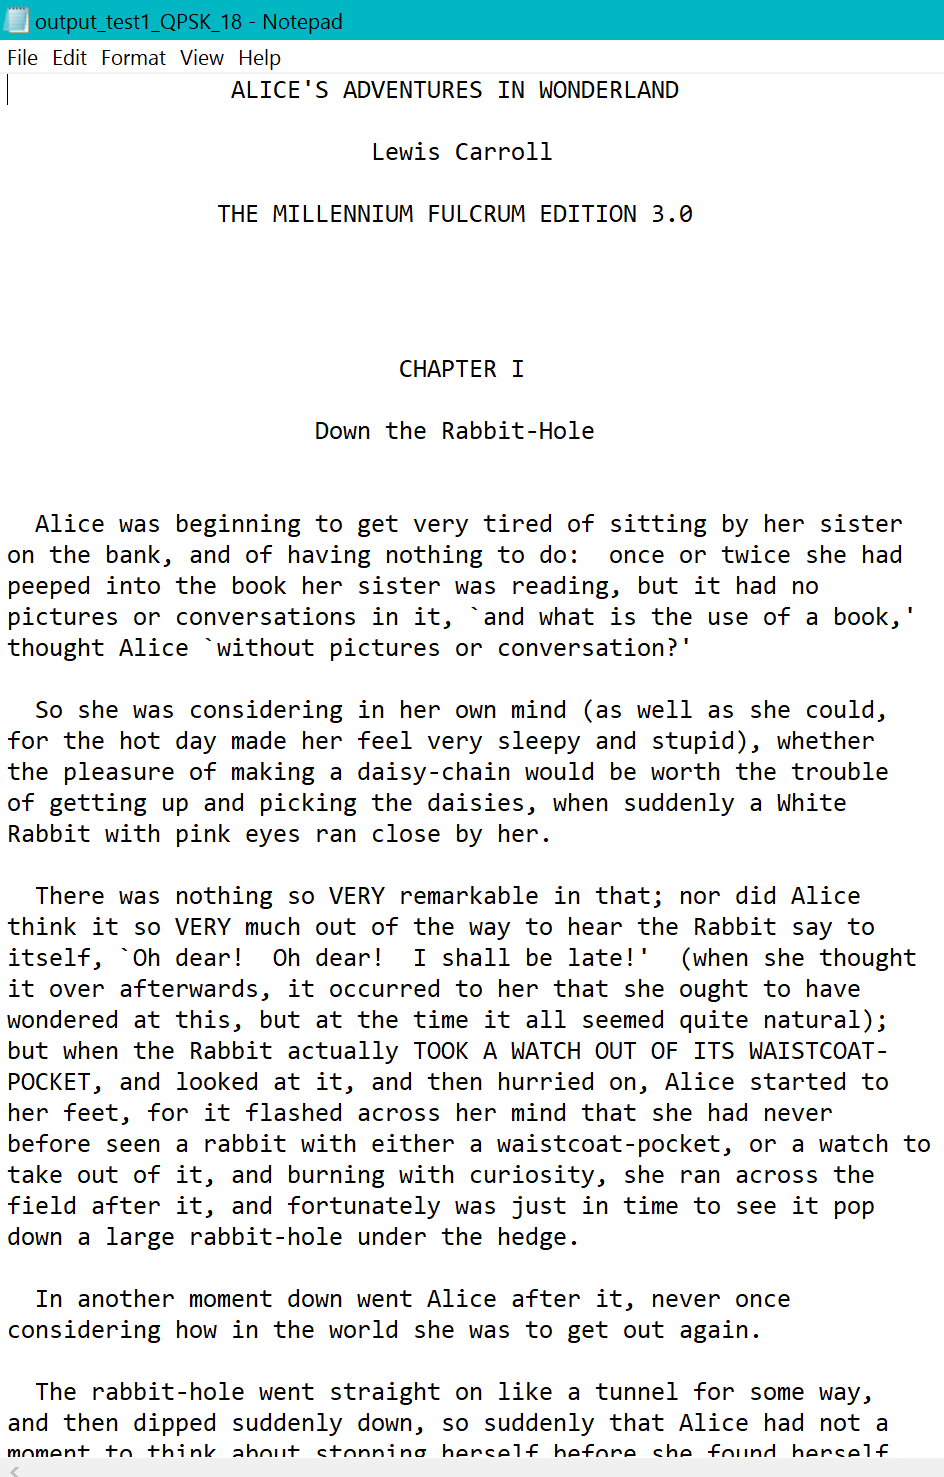

- **24 Mbps, 16QAM, 1/2**

clc
clear all
close all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 24; codeRate = 1/2; modulation_type = '16QAM'; rep_type = 'Float'; equalization_method = 'WE';
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
%transmitted_frames = filter(h,1,transmitted_frames); 
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
%Receiver
[decoded_data, rec_frames, eq_rec_fremaes ] = Receiver(transmitted_frames, equalization_method, rep_type);
output_fileID = fopen('output_test1_16QAM_24.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');


Received Text File

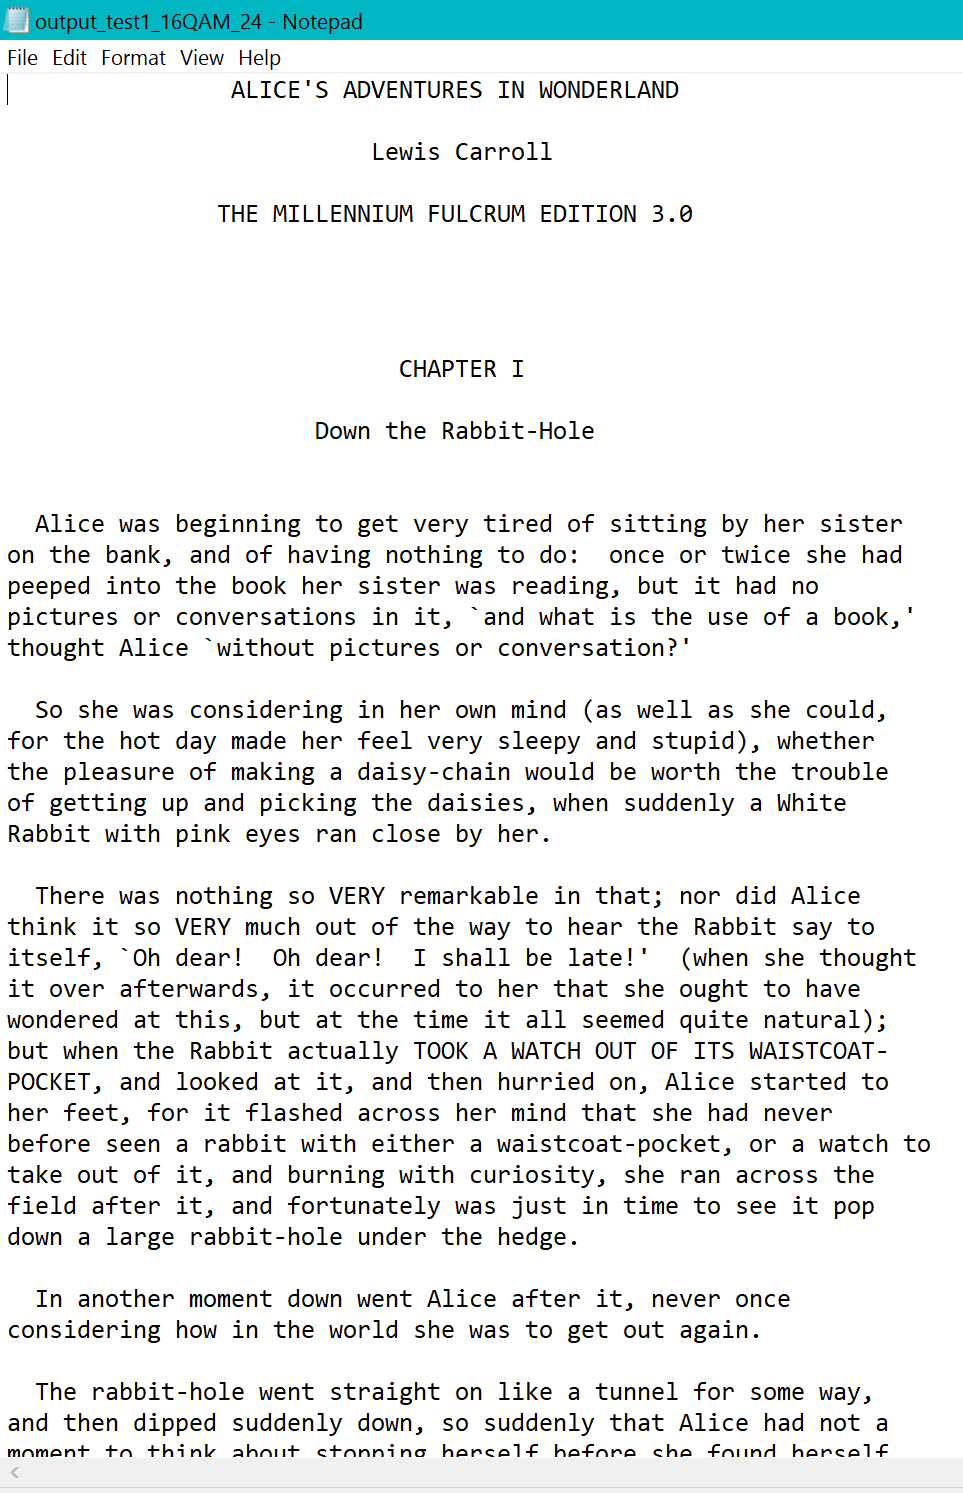

- **36 Mbps, 16QAM, 3/4**

clc
clear all
close all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 36; codeRate = 3/4; modulation_type = '16QAM'; rep_type = 'Float'; equalization_method = 'WE';
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
%transmitted_frames = filter(h,1,transmitted_frames); 
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
%Receiver
[decoded_data, rec_frames, eq_rec_fremaes ] = Receiver(transmitted_frames, equalization_method, rep_type);
output_fileID = fopen('output_test1_16QAM_36.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');


Received Text File

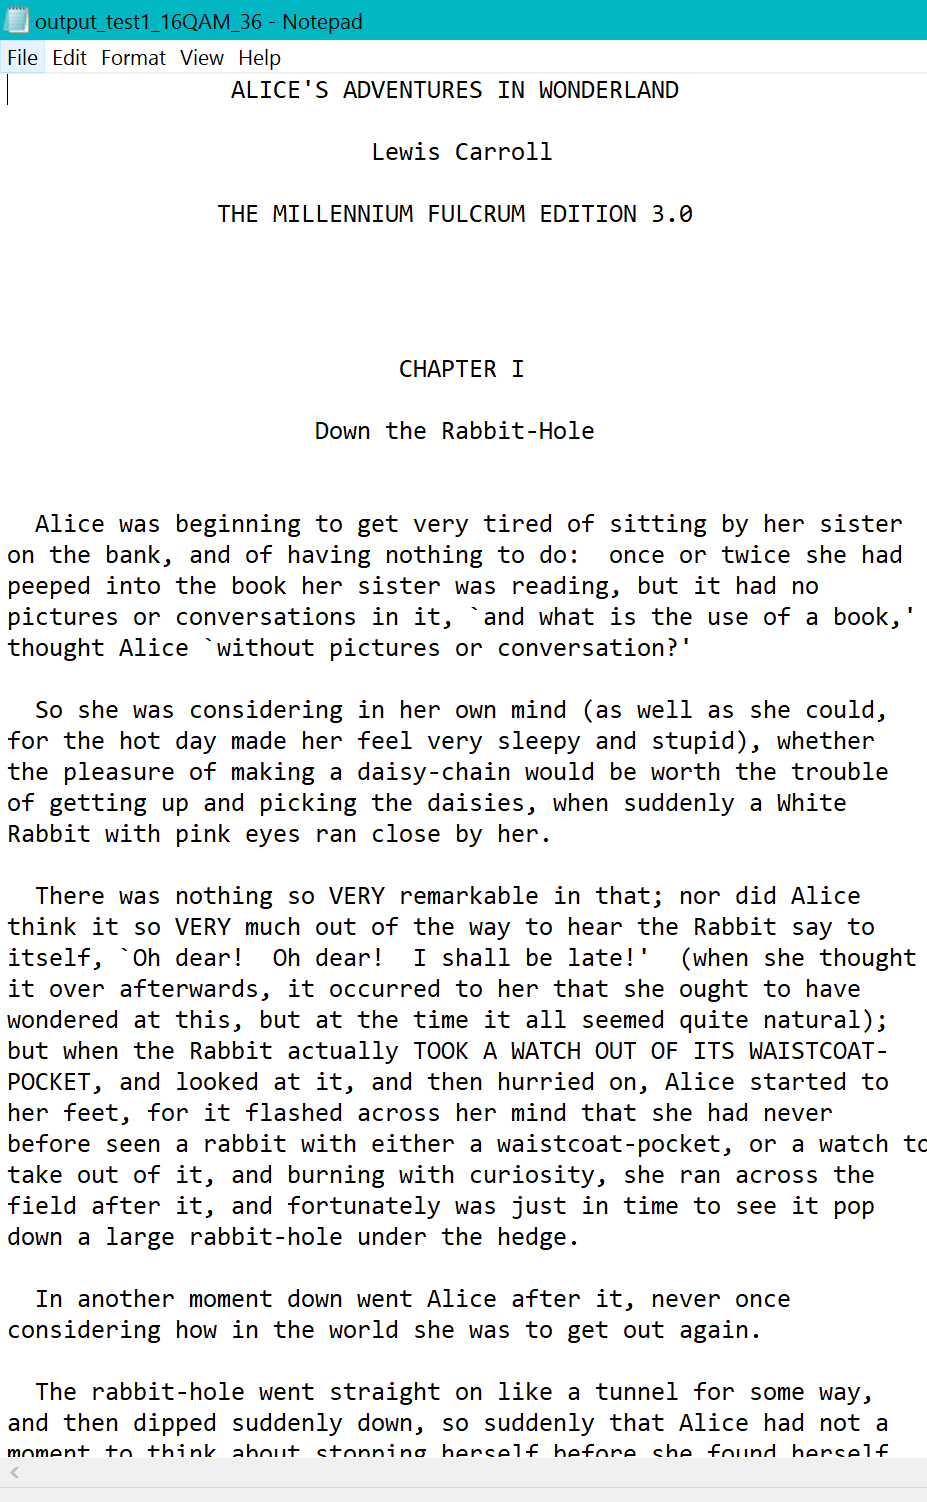

- **48 Mbps, 64QAM, 2/3**

clc
clear all
close all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 48; codeRate = 2/3; modulation_type = '64QAM'; rep_type = 'Float'; equalization_method = 'WE';
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
%transmitted_frames = filter(h,1,transmitted_frames); 
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
%Receiver
[decoded_data, rec_frames, eq_rec_fremaes ] = Receiver(transmitted_frames, equalization_method, rep_type);
output_fileID = fopen('output_test1_64QAM_48.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');


Received Text File

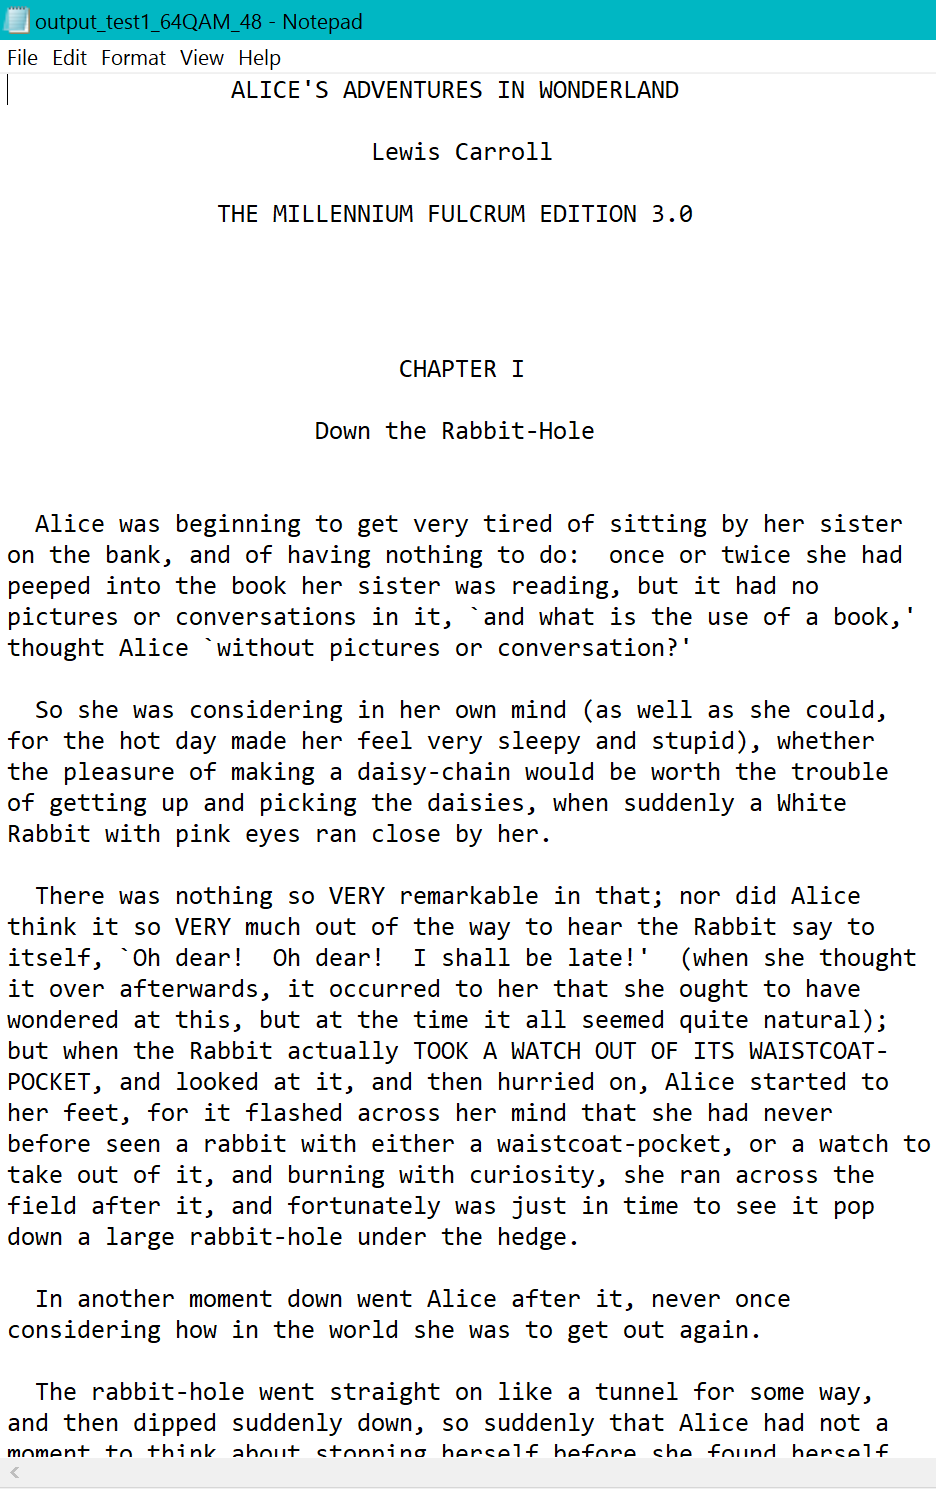

- **54 Mbps, 64QAM, 3/4**

clc
clear all
close all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 54; codeRate = 3/4; modulation_type = '64QAM'; rep_type = 'Float'; equalization_method = 'WE';
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
%transmitted_frames = filter(h,1,transmitted_frames); 
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
%Receiver
[decoded_data, rec_frames, eq_rec_fremaes ] = Receiver(transmitted_frames, equalization_method, rep_type);
output_fileID = fopen('output_test1_64QAM_54.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');


Received Text File

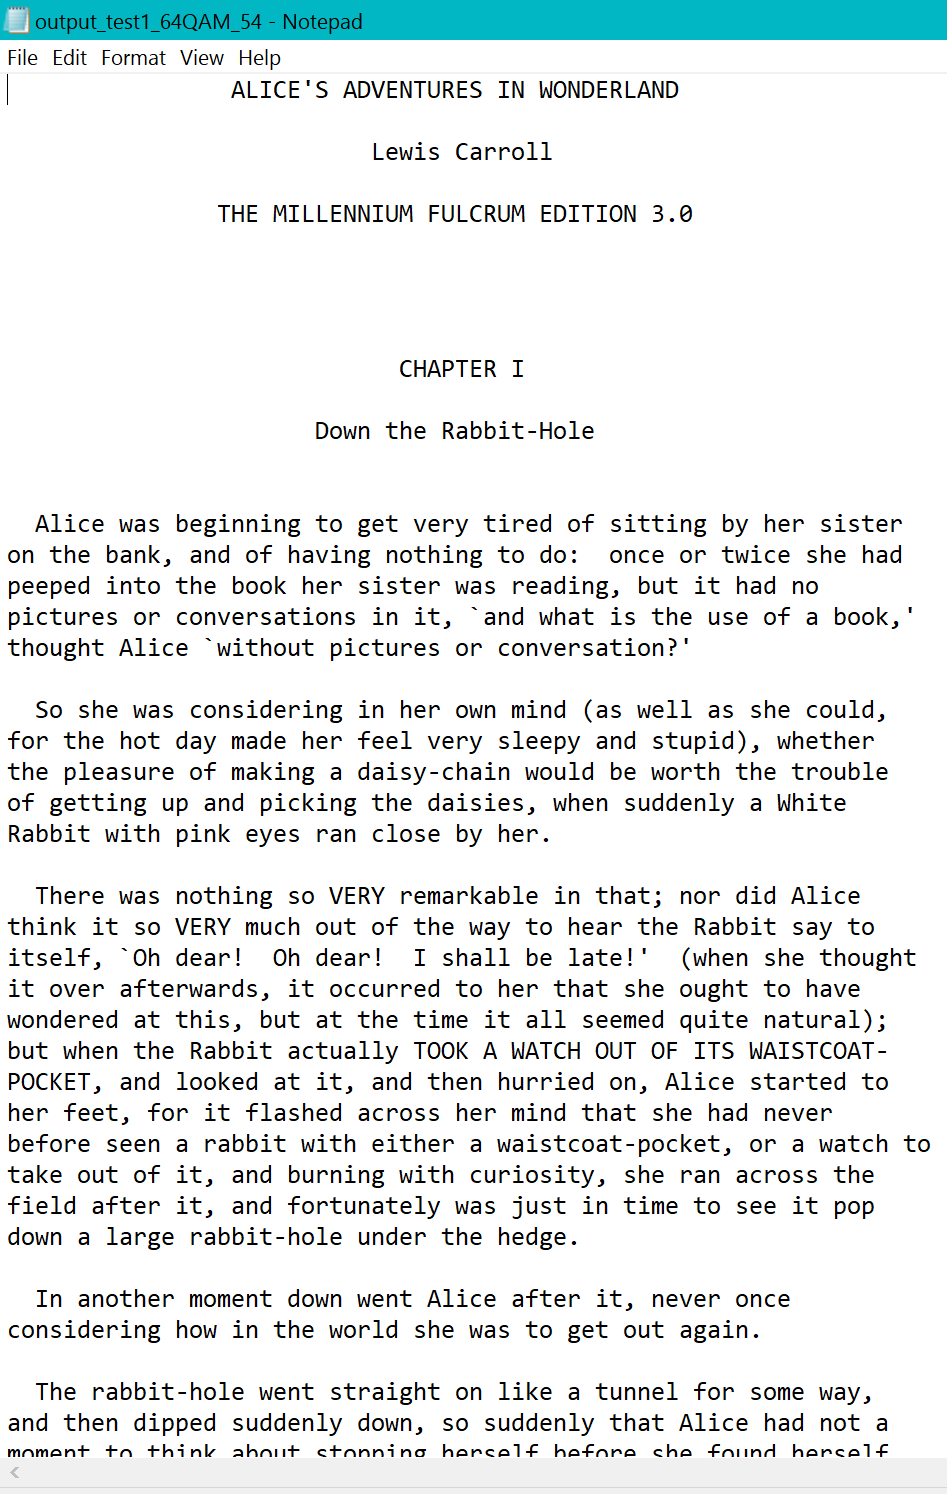

### **B) ** **Comparison between BER of the ZF and Weiner equalizer for 64QAM modulation, and 3/4 code rate (floating-point)**

- **The WE (LMMSE Equalizer) performance is slightly better than ZF Equalizer, but they are behaving in the same manner for high SNR. **

- **Due to the noise enhancement in ZF Equalizer, its performance is worse than WE.**

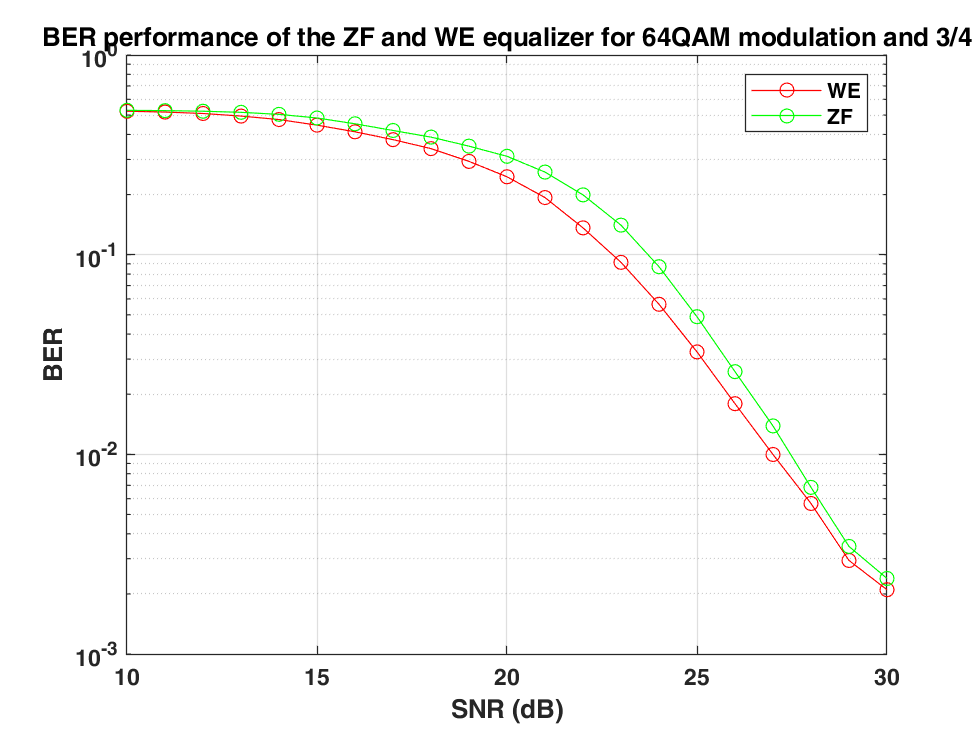

clc
clear all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 54; codeRate = 3/4; modulation_type = '64QAM'; rep_type = 'Float';
%Comparison
SNR_dB = [10:1:30]; SNR_lin = 10.^(SNR_dB/10); BER_ZF = []; BER_WE = [];
for snr = SNR_dB
    %Frame Construction and Transmitter
    transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
    transmitted_frames = conv(transmitted_frames,conj(h));
    transmitted_frames = transmitted_frames(1:end-length(h)+1);
    % Noise
    y = awgn(transmitted_frames, snr,'measured');
    %Receiver
    [decoded_data_WE, rec_frames_WE, eq_rec_fremaes_WE ] = Receiver(y, 'WE', rep_type, snr);
    [decoded_data_ZF, rec_frames_ZF, eq_rec_fremaes_ZF ] = Receiver(y, 'ZF', rep_type, snr);
    %BER
    [NUMBER_WE, RATIO_WE] = biterr(decoded_data_WE',data);
    BER_WE = [BER_WE RATIO_WE];
    [NUMBER_ZF, RATIO_ZF] = biterr(decoded_data_ZF',data);
    BER_ZF = [BER_ZF RATIO_ZF]; 
end

figure();
semilogy(SNR_dB, BER_ZF,'r-o', SNR_dB, BER_WE,'g-o');
title('BER performance of the ZF and WE equalizer for 64QAM modulation and 3/4');
xlabel('SNR (dB)'); ylabel('BER');
legend('WE', 'ZF ');
grid on;



### **C) **Constellation diagram of the received symbols after equalization using the ZF equalizer, and the Weiner equalizer for 64QAM modulation, and 3/4 code rate using the floating-point implementation at any SNR of your choice (one figure for each equalizer) 

- **For low SNR, it is clearly shown that the performance of WE (LMMSE equalizer) is better than the performance of ZF equalizer. This is due to noise enhancement effect is shown in the abnormal high constellation values.**

- **For high SNR, both WE and ZF equalizers showed a similar performance based on the constellation diagram. **

**SNR = 10 dB**

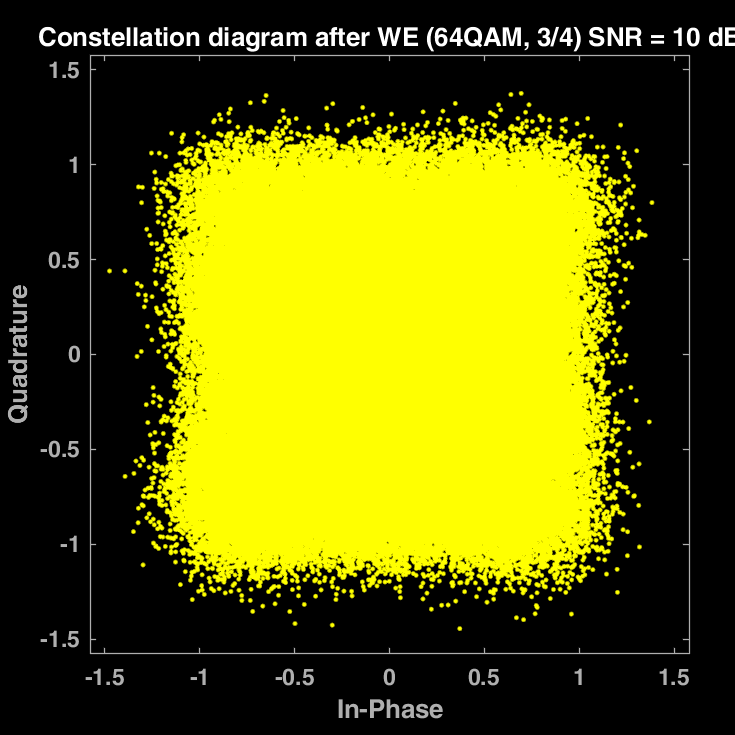

clc
clear all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 54; codeRate = 3/4; modulation_type = '64QAM'; rep_type = 'Float'; equalization_method = 'WE';
%Noise
SNR_dB = 10;
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
% Noise
y = awgn(transmitted_frames, SNR_dB,'measured');    
%Receiver
[decoded_data_WE, rec_frames_WE, eq_rec_fremaes_WE ] = Receiver(y, 'WE', rep_type, SNR_dB);
[decoded_data_ZF, rec_frames_ZF, eq_rec_fremaes_ZF ] = Receiver(y, 'ZF', rep_type, SNR_dB); 
scatterplot(eq_rec_fremaes_WE);
title('Constellation diagram after WE (64QAM, 3/4) SNR = 10 dB');
xlabel('In-Phase'); ylabel('Quadrature');

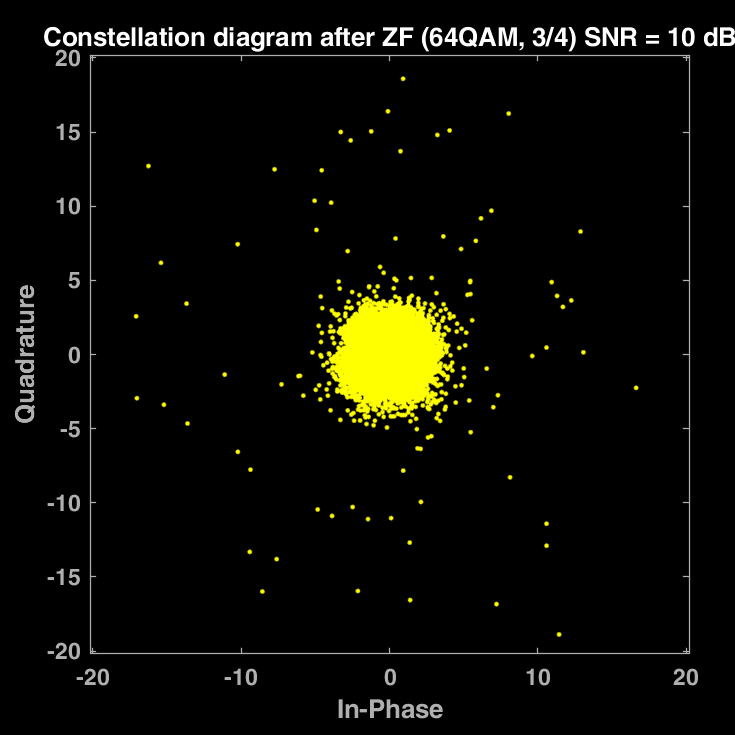

scatterplot(eq_rec_fremaes_ZF);
title('Constellation diagram after ZF (64QAM, 3/4) SNR = 10 dB');
xlabel('In-Phase'); ylabel('Quadrature');

**SNR = 30 dB**

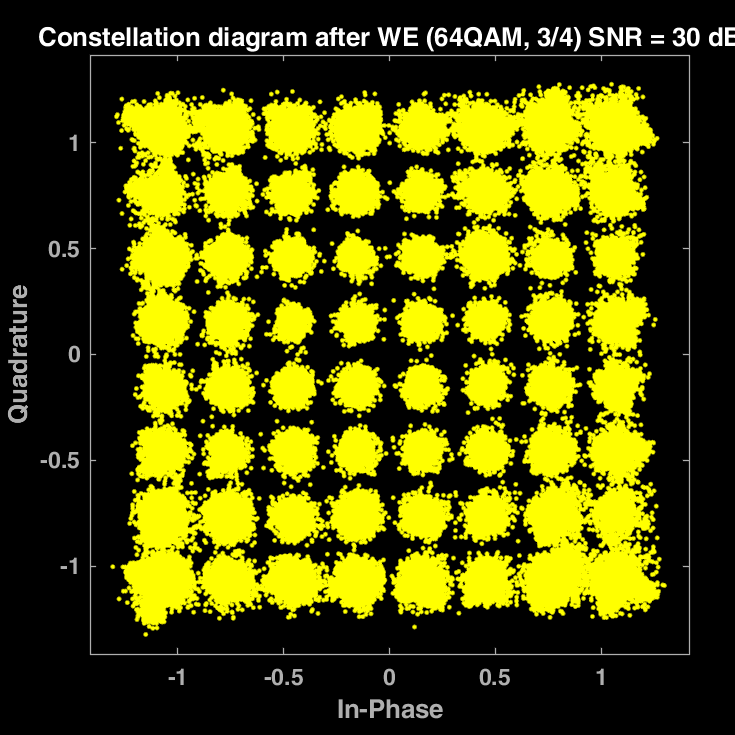

clc
clear all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 54; codeRate = 3/4; modulation_type = '64QAM'; rep_type = 'Float'; equalization_method = 'WE';
%Noise
SNR_dB = 30;
%Frame Construction and Transmitter
transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
transmitted_frames = conv(transmitted_frames,conj(h));
transmitted_frames = transmitted_frames(1:end-length(h)+1);
% Noise
y = awgn(transmitted_frames, SNR_dB,'measured');    
%Receiver
[decoded_data_WE, rec_frames_WE, eq_rec_fremaes_WE ] = Receiver(y, 'WE', rep_type, SNR_dB);
[decoded_data_ZF, rec_frames_ZF, eq_rec_fremaes_ZF ] = Receiver(y, 'ZF', rep_type, SNR_dB); 
scatterplot(eq_rec_fremaes_WE);
title('Constellation diagram after WE (64QAM, 3/4) SNR = 30 dB');
xlabel('In-Phase'); ylabel('Quadrature');

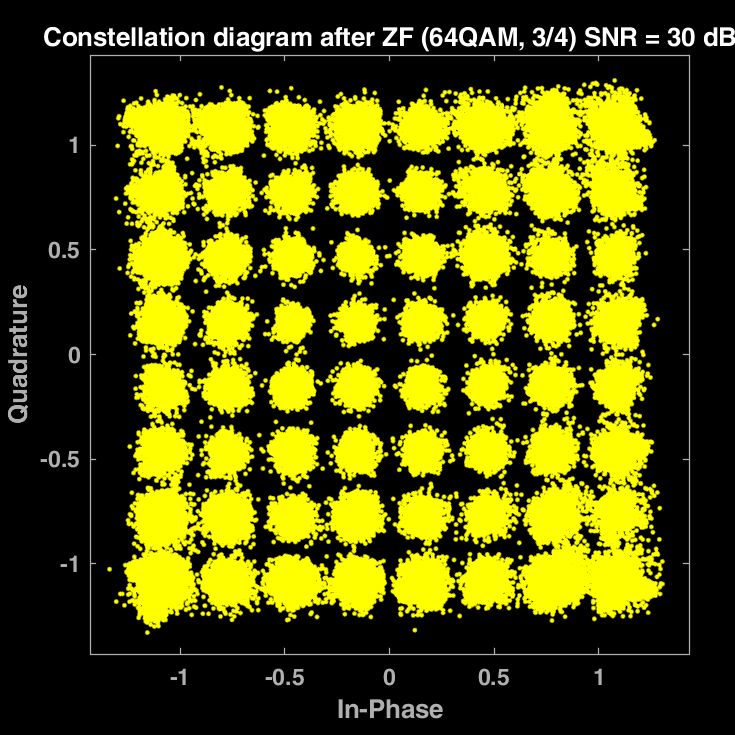

scatterplot(eq_rec_fremaes_ZF);
title('Constellation diagram after ZF (64QAM, 3/4) SNR = 30 dB');
xlabel('In-Phase'); ylabel('Quadrature');

### **D) ** Comparison between the BER performance of the floating-point and fixed-point implementations for 16QAM modulation, and 3/4 code rate  

- **As shown in the figure, the BER of Float-point implementation is less than Fixed-point implementation as expected.**

- **BER of both Fixed and Float point implementation using WE are smaller than the BER using ZF Equalizer.**

- **BER of WE using Float point implementation is less than WE using Fixed point implementation.**

- **BER of ZF using Float point implementation is less than ZF using Fixed point implementation.**

- **All of them behave in the same manner for high SNR.**

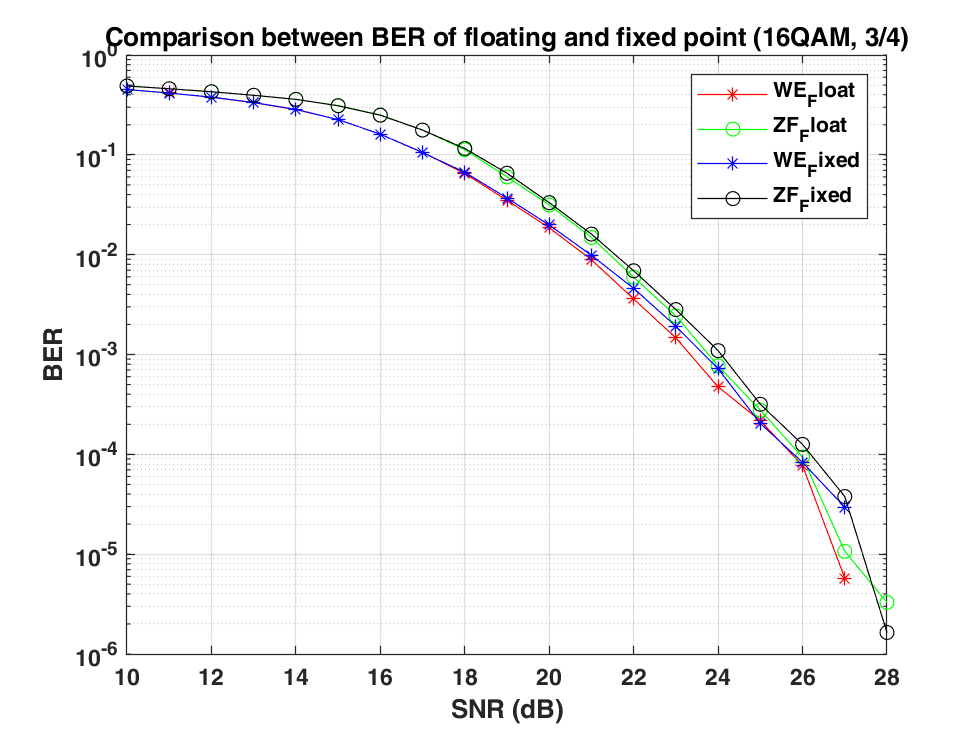

Unrecognized function or variable 'Comparison'.

clc
clear all
% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000; R = 36; codeRate = 3/4; modulation_type = '16QAM';
SNR_dB = [10:1:30]; BER_ZF = []; BER_WE = []; BER_ZF_f = []; BER_WE_f = [];

%Floating Point
for snr = SNR_dB
    %Frame Construction and Transmitter
    transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, 'Float');
    % Channel
    h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
    transmitted_frames = conv(transmitted_frames,conj(h));
    transmitted_frames = transmitted_frames(1:end-length(h)+1); 
    % Noise
    y = awgn(transmitted_frames, snr,'measured');
    %Receiver
    [decoded_data_WE, rec_frames_WE, eq_rec_fremaes_WE ] = Receiver(y, 'WE', 'Float', snr);
    [decoded_data_ZF, rec_frames_ZF, eq_rec_fremaes_ZF ] = Receiver(y, 'ZF', 'Float', snr);
    %BER
    [NUMBER_WE, RATIO_WE] = biterr(decoded_data_WE',data);
    BER_WE = [BER_WE RATIO_WE];
    [NUMBER_ZF, RATIO_ZF] = biterr(decoded_data_ZF',data);
    BER_ZF = [BER_ZF RATIO_ZF];
end

%%
%Fixed Point
for snr = SNR_dB
    %Frame Construction and Transmitter
    transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, 'Fixed');
    % Channel
    h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
    transmitted_frames = conv(transmitted_frames,conj(h));
    transmitted_frames = transmitted_frames(1:end-length(h)+1); 
    % Noise
    y = awgn(transmitted_frames.data, snr,'measured');
    y = fi(y,1,8,8);
    %Receiver
    [decoded_data_WE_f, rec_frames_WE_f, eq_rec_fremaes_WE_f ] = Receiver(y, 'WE', 'Fixed', snr);
    [decoded_data_ZF_f, rec_frames_ZF_f, eq_rec_fremaes_ZF_F ] = Receiver(y, 'ZF', 'Fixed', snr);
    %BER
    [NUMBER_WE_f, RATIO_WE_f] = biterr(decoded_data_WE_f',data);
    BER_WE_f = [BER_WE_f RATIO_WE_f];
    [NUMBER_ZF_f, RATIO_ZF_f] = biterr(decoded_data_ZF_f',data);
    BER_ZF_f = [BER_ZF_f RATIO_ZF_f];
end

%%
figure();
semilogy(SNR_dB, BER_ZF,'r-*', SNR_dB, BER_WE,'g-o', SNR_dB, BER_ZF_f,'b-*', SNR_dB, BER_WE_f,'k-o');
title('Comparison between BER of floating and fixed point (16QAM, 3/4)');
xlabel('SNR (dB)'); ylabel('BER');
legend('WE_Float', 'ZF_Float', 'WE_Fixed', 'ZF_Fixed');
grid on;

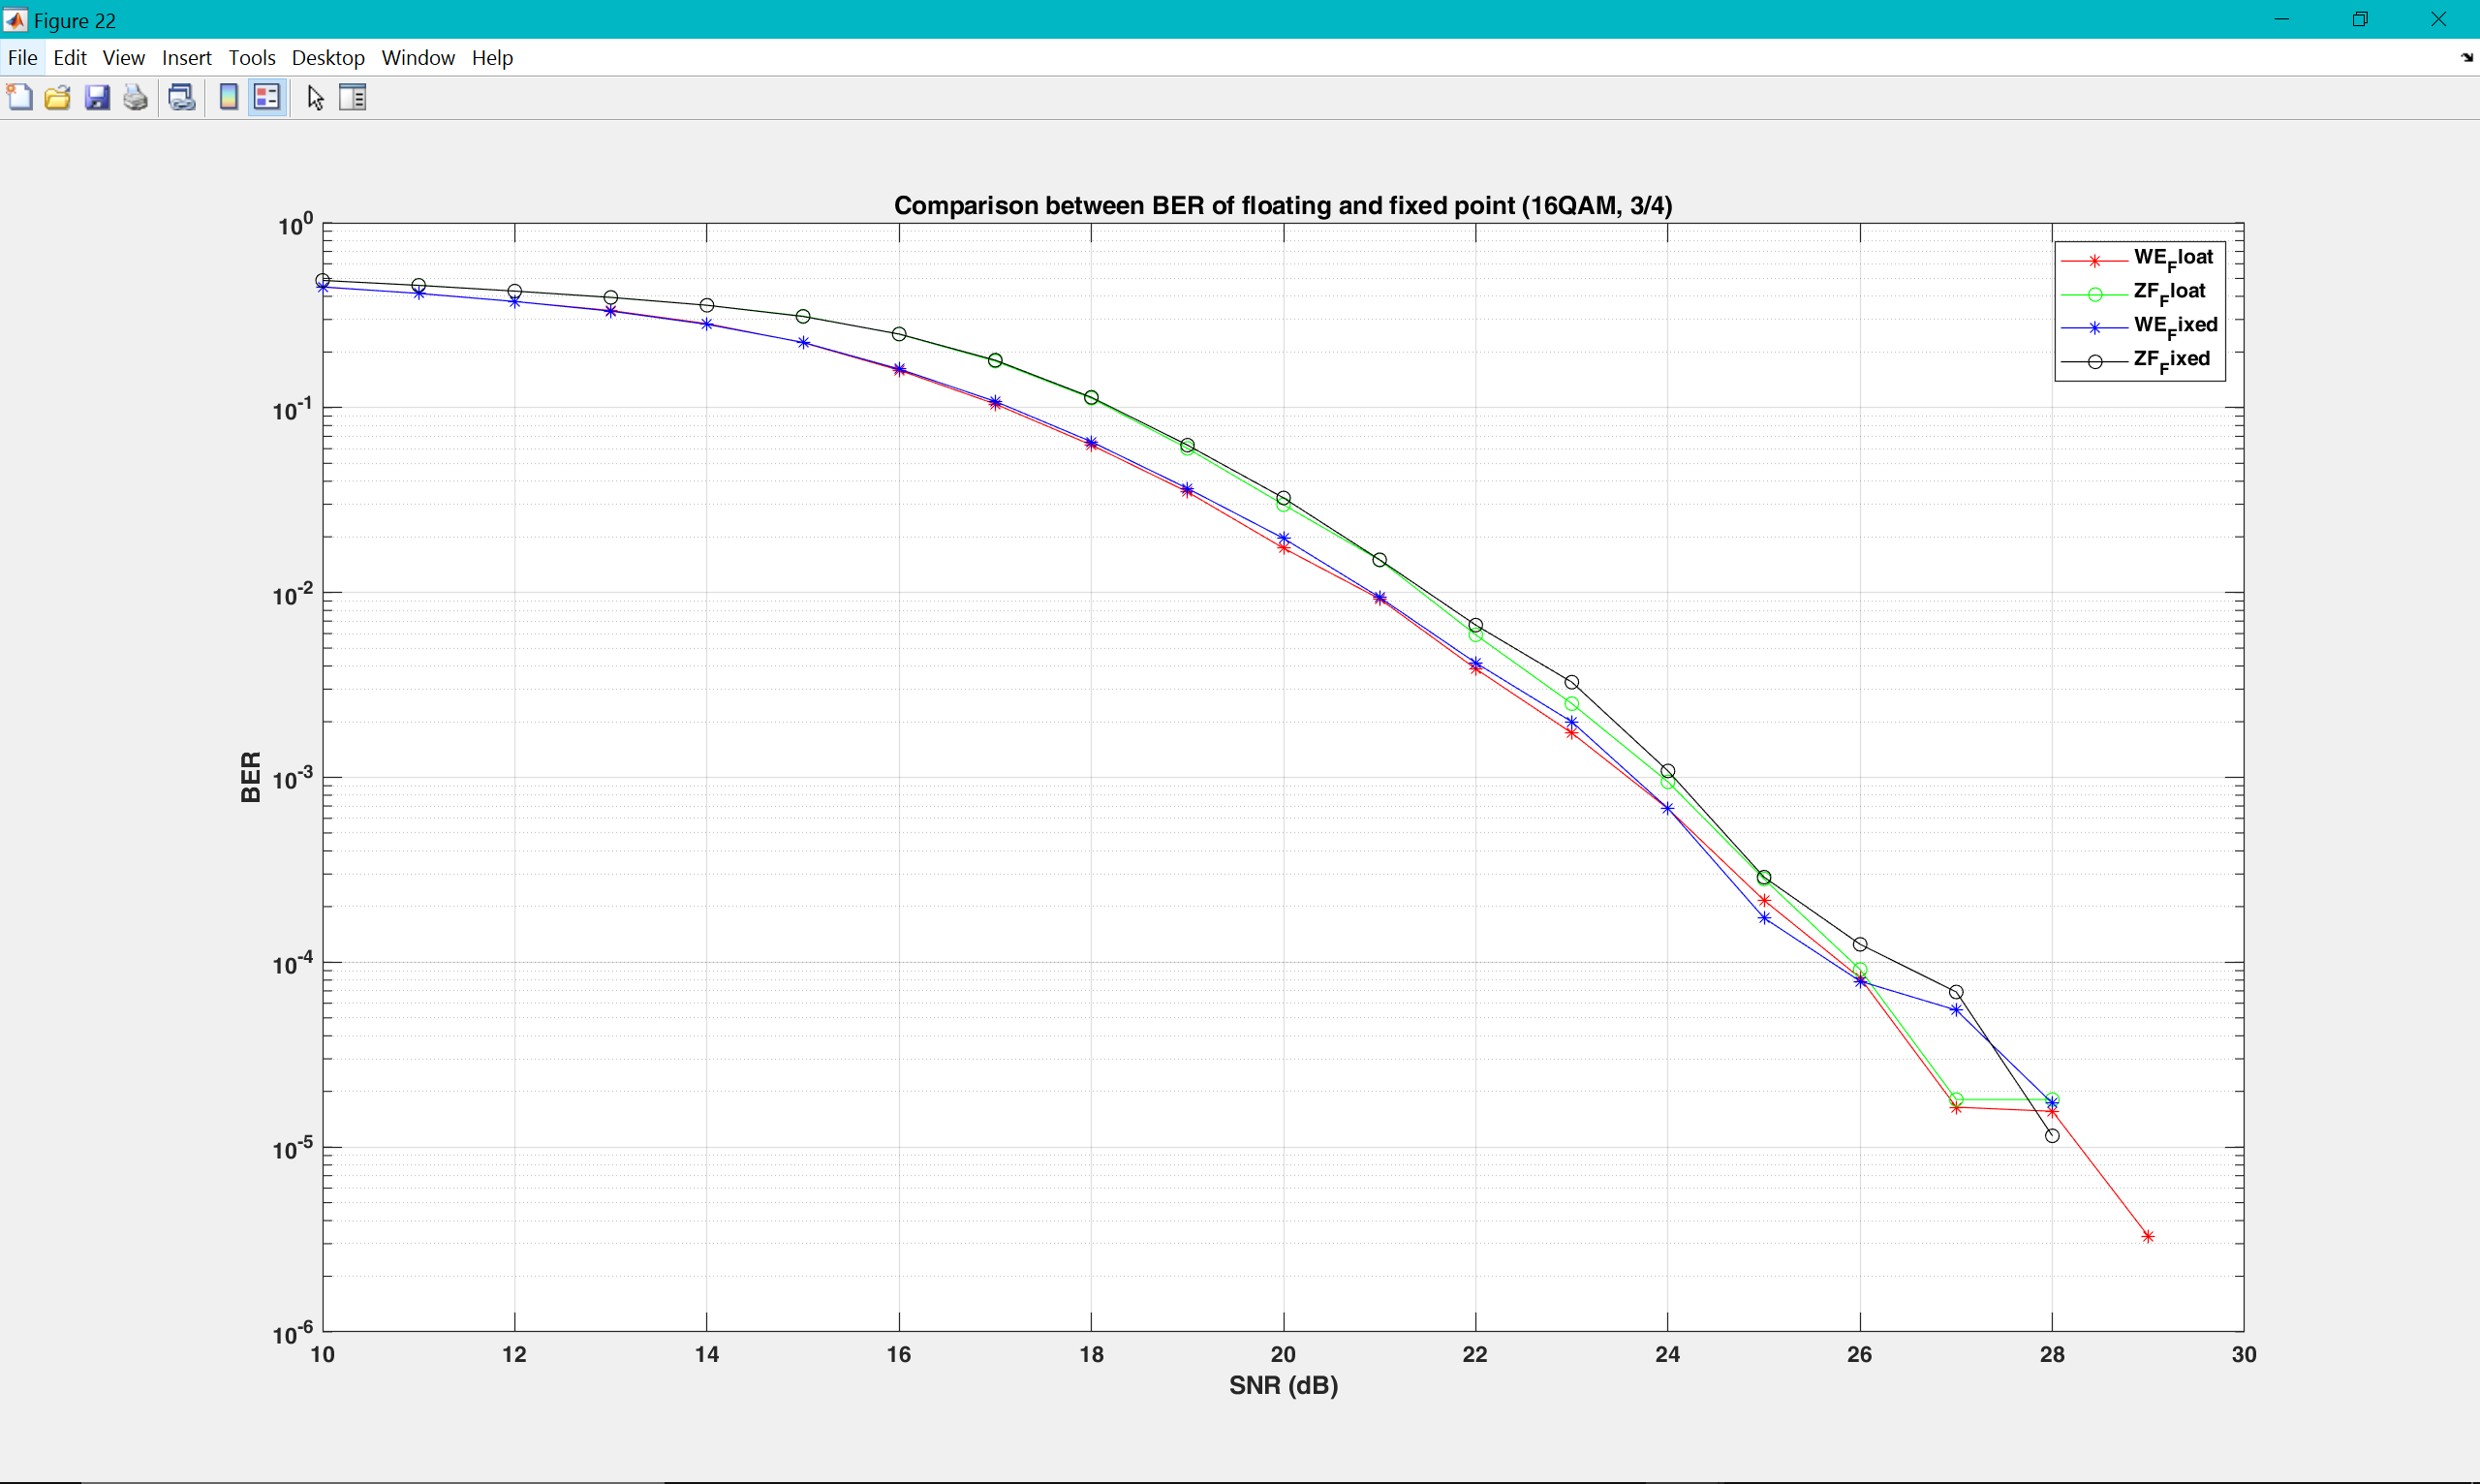

### **E) ** Comparison between the BER performance of all supported rates using the floating-point implementation  

- **The resulted figure shows how BER changes with changing the modulation schemes and invistigate the trade-off between choosing higher rates and BER.**

- **The figure shows that BPSK with Code Rate = 1/2 is the one with the lowest BER as expected.**

- **The modulation scheme with the highest BER is 64QAM with 3/4 code rate.**

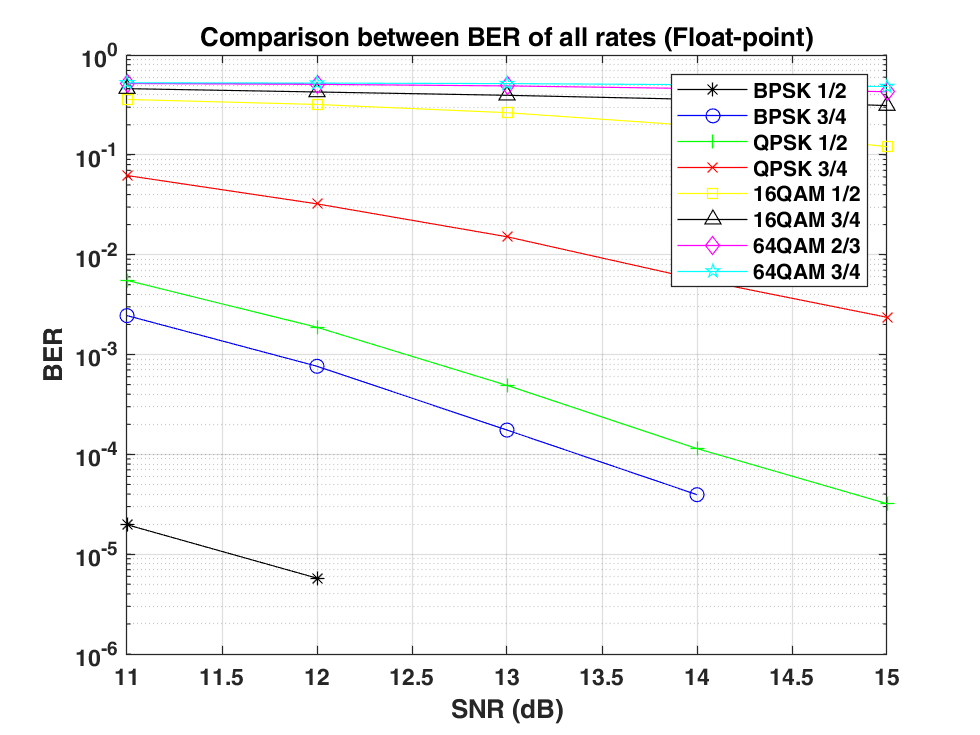

clc
clear all

% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
figure();
CRv= [1/2, 3/4, 1/2, 3/4, 1/2, 3/4, 2/3, 3/4];
mod_typesv = ["BPSK","BPSK","QPSK", "QPSK", "16QAM", "16QAM", "64QAM", "64QAM"];
Rv = [6, 9, 12, 18, 24, 36, 48, 54];
L = 1000; R = 54; codeRate = 3/4; modulation_type = '64QAM'; rep_type = 'Float'; equalization_method = 'WE';
colors = ["k-*","b-o","g-+", "r-x","y-s","k-^","m-d","c-p"]; % fol plotting
%markers = ['o', '+', '*', 'x', 's', '^', 'd', 'p'];
%Comparison
SNR_dB = [11:1:25]; 
for o = 1: length(Rv)
    R = Rv(o); codeRate = CRv(o); modulation_type = mod_typesv(o); 
    BER_WE = [];
    for snr = SNR_dB
    %Frame Construction and Transmitter
    transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
    transmitted_frames = conv(transmitted_frames,conj(h));
    transmitted_frames = transmitted_frames(1:end-length(h)+1);
    % Noise
    y = awgn(transmitted_frames, snr,'measured');
    %Receiver
    [decoded_data_WE, rec_frames_WE, eq_rec_fremaes_WE ] = Receiver(y, 'WE', rep_type, snr);
    %BER
    [NUMBER_WE, RATIO_WE] = biterr(decoded_data_WE',data);
    BER_WE = [BER_WE RATIO_WE];  
    end
    semilogy(SNR_dB, BER_WE, colors(o));
    hold on;
end
hold off;
title('Comparison between BER of all rates (Float-point)');
xlabel('SNR (dB)'); ylabel('BER');
legend('BPSK 1/2','BPSK 3/4','QPSK 1/2','QPSK 3/4','16QAM 1/2','16QAM 3/4','64QAM 2/3','64QAM 3/4');
grid on;
xlim([11 15]);

### **F) ** Comparison between the BER performance of all supported rates using the fixed-point implementation  

- **The resulted figure shows how BER changes with changing the modulation schemes and invistigate the trade-off between choosing higher rates and BER.**

- **The figure shows that BPSK with Code Rate = 1/2 is the one with the lowest BER as expected.**

- **The modulation scheme with the highest BER is 64QAM with 3/4 code rate.**

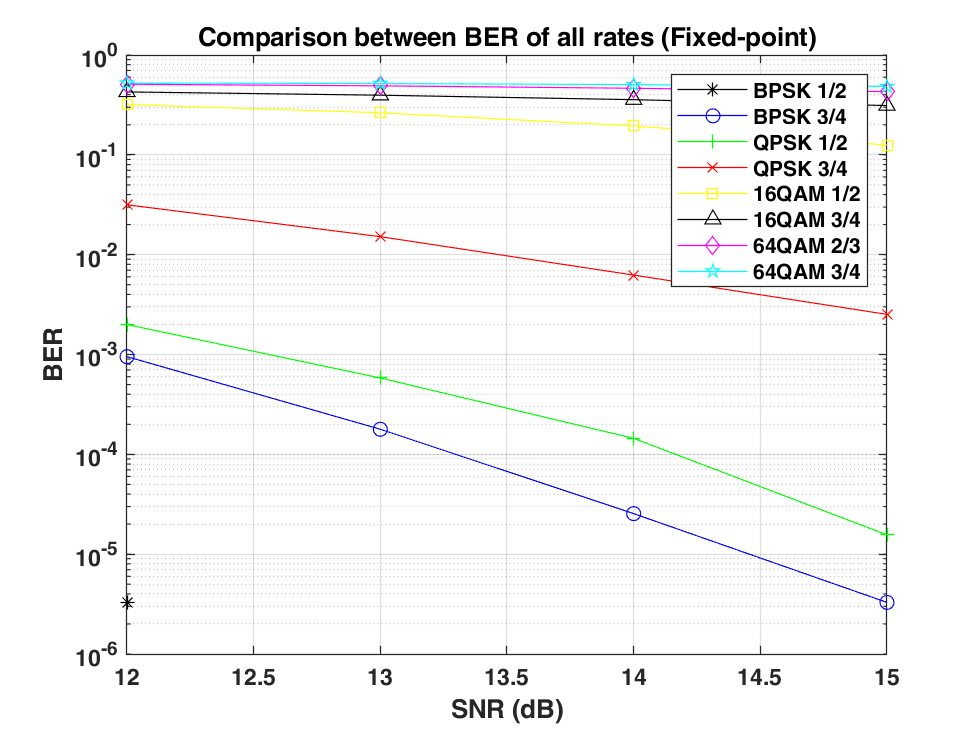

clc
clear all

% Parameters
filename='test_file_1.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
figure();
CRv= [1/2, 3/4, 1/2, 3/4, 1/2, 3/4, 2/3, 3/4];
mod_typesv = ["BPSK","BPSK","QPSK", "QPSK", "16QAM", "16QAM", "64QAM", "64QAM"];
Rv = [6, 9, 12, 18, 24, 36, 48, 54];
L = 1000; R = 54; codeRate = 3/4; modulation_type = '64QAM'; rep_type = 'Fixed'; equalization_method = 'WE';
colors = ["k-*","b-o","g-+", "r-x","y-s","k-^","m-d","c-p"]; % fol plotting
%Comparison
SNR_dB = [12:1:15]; 

for o = 1: length(Rv)
    R = Rv(o); codeRate = CRv(o); modulation_type = mod_typesv(o); 
    BER_WE = [];
    for snr = SNR_dB
    %Frame Construction and Transmitter
    transmitted_frames = Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    
    
    % Channel
    h = [0.8208 + 0.2052*1i, 0.4104 + 0.1026*1i, 0.2052 + 0.2052*1i, 0.1026 + 0.1026*1i]; %Channel
    transmitted_frames = conv(transmitted_frames,conj(h));
    transmitted_frames = transmitted_frames(1:end-length(h)+1);
    
    % Noise
    y = awgn(transmitted_frames.data, snr,'measured');
    y = fi(y,1,8,8);
    %Receiver
    [decoded_data_WE, rec_frames_WE, eq_rec_fremaes_WE ] = Receiver(y, 'WE', rep_type, snr);
    
    %BER
    [NUMBER_WE, RATIO_WE] = biterr(decoded_data_WE',data);
    BER_WE = [BER_WE RATIO_WE];
        
    end
    semilogy(SNR_dB, BER_WE, colors(o));
    hold on;
end

hold off;
title('Comparison between BER of all rates (Fixed-point)');
xlabel('SNR (dB)'); ylabel('BER');
legend('BPSK 1/2','BPSK 3/4','QPSK 1/2','QPSK 3/4','16QAM 1/2','16QAM 3/4','64QAM 2/3','64QAM 3/4');
grid on;
xlim([12 15]);